# computer assignment 2

## IBME

### Amirhossein Tayebi - 810198430

%filenames=["data set\data\Abnormal 1.m4a","data set\data\Abnormal 2.m4a","data set\data\Abnormal 3.m4a""data set\data\Abnormal 4.m4a""data set\data\Abnormal 5.m4a""data set\data\Abnormal 6.m4a""data set\data\Abnormal 7.m4a""data set\data\Abnormal 8.m4a""data set\data\Abnormal 1.m4a""data set\data\Abnormal 1.m4a""data set\data\Abnormal 1.m4a""data set\data\Abnormal 1.m4a""data set\data\Abnormal 1.m4a""data set\data\Abnormal 1.m4a""data set\data\Abnormal 1.m4a""data set\data\Abnormal 1.m4a""data set\data\Abnormal 1.m4a""data set\data\Abnormal 1.m4a""data set\data\Abnormal 1.m4a""data set\data\Abnormal 1.m4a""data set\data\Abnormal 1.m4a""data set\data\Abnormal 1.m4a""data set\data\Abnormal 1.m4a""data set\data\Abnormal 1.m4a""data set\data\Abnormal 1.m4a""data set\data\Abnormal 1.m4a""data set\data\Abnormal 1.m4a""data set\data\Abnormal 1.m4a""data set\data\Abnormal 1.m4a""data set\data\Abnormal 1.m4a""data set\data\Abnormal 1.m4a""data set\data\Abnormal 1.m4a""data set\data\Abnormal 1.m4a""data set\data\Abnormal 1.m4a""data set\data\Abnormal 1.m4a""data set\data\Abnormal 1.m4a""data set\data\Abnormal 1.m4a""data set\data\Abnormal 1.m4a""data set\data\Abnormal 1.m4a"]


%loading audio files
fs=44100;
a=44100*5;
data=zeros(40,a);
folder='data set\data';
audio_files=dir(fullfile(folder));
for k=3:numel(audio_files)
  filename=audio_files(k).name;

    y=audioread(strcat(folder,'/',filename));
    data(k-2,:)=y(1:a);
end

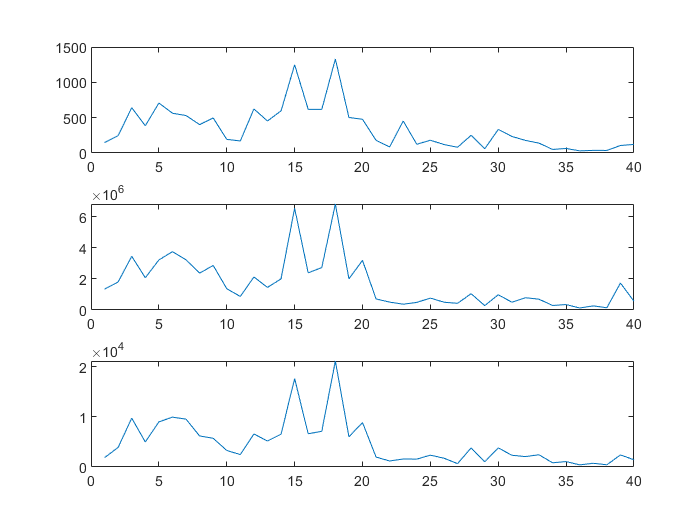

%features
features=zeros(40,3);
for i=1:40
    y0=fft(data(i,:));
    d=abs(y0);
    features(i,1)=max(d);
    features(i,2)=sum(d);
    features(i,3)=sum(abs(data(i,:)));
end
subplot(3,1,1,"replace");
plot(features(:,1));
subplot(3,1,2,"replace");
plot(features(:,2));
subplot(3,1,3,"replace");
plot(features(:,3));

feat(1)=min(features(1:20,1));
feat(2)=min(features(1:20,2));
feat(3)=min(features(1:20,3));
% df = fs/a;
% freq = 0:df:fs-df;
% plot(freq,abs(y0));


%finding tn,tp,fn,fp
for i=1:40
    n=0;
    if (features(i,1)>feat(1)) n=n+1; end
     if (features(i,2)>feat(2)) n=n+1; end
      if (features(i,3)>feat(3)) n=n+1; end
    if (n>1) disp(strcat(audio_files(i+2).name,' is decided to be abnormal')); end
    if (n<1) disp(strcat(audio_files(i+2).name,' is decided to be normal')); end
    
    
    
end

Abnormal 10.m4a is decided to be abnormal
Abnormal 11.m4a is decided to be abnormal
Abnormal 12.m4a is decided to be abnormal
Abnormal 13.m4a is decided to be abnormal
Abnormal 14.m4a is decided to be abnormal
Abnormal 15.m4a is decided to be abnormal
Abnormal 16.m4a is decided to be abnormal
Abnormal 17.m4a is decided to be abnormal
Abnormal 18.m4a is decided to be abnormal
Abnormal 19.m4a is decided to be abnormal
Abnormal 2.m4a is decided to be abnormal
Abnormal 20.m4a is decided to be abnormal
Abnormal 3.m4a is decided to be abnormal
Abnormal 4.m4a is decided to be abnormal
Abnormal 5.m4a is decided to be abnormal
Abnormal 6.m4a is decided to be abnormal
Abnormal 7.m4a is decided to be abnormal
Abnormal 8.m4a is decided to be abnormal
Abnormal 9.m4a is decided to be abnormal
Normal 1.m4a is decided to be abnormal


Normal 10.m4a is decided to be normal
Normal 12.m4a is decided to be normal


Normal 13.m4a is decided to be abnormal


Normal 14.m4a is decided to be normal
Normal 15.m4a is decided to be normal


Normal 16.m4a is decided to be abnormal


Normal 17.m4a is decided to be normal


Normal 18.m4a is decided to be abnormal
Normal 19.m4a is decided to be abnormal
Normal 2.m4a is decided to be abnormal


Normal 3.m4a is decided to be normal
Normal 4.m4a is decided to be normal
Normal 5.m4a is decided to be normal
Normal 6.m4a is decided to be normal
Normal 7.m4a is decided to be normal


Normal 8.m4a is decided to be abnormal


Normal 9.m4a is decided to be normal


%validation
foldert='data set\test';

test_files=dir(fullfile(foldert));
for k=3:numel(test_files)
  filename=test_files(k).name;
    y=audioread(strcat(foldert,'/',filename));
    y0=fft(y);
     d=abs(y0);
    f(1)=max(d);
    f(2)=sum(d);
    f(3)=sum(abs(y));
    n=0;
    if (f(1)>feat(1)) n=n+1; end
     if (f(2)>feat(2)) n=n+1; end
      if (f(3)>feat(3)) n=n+1; end
    if (n>1) disp(strcat(filename,' is decided to be abnormal')); end
    if (n<1) disp(strcat(filename,' is decided to be normal')); end
end

Test abnormal 1.m4a is decided to be abnormal
Test abnormal 2.m4a is decided to be abnormal
Test abnormal 3.m4a is decided to be abnormal
Test abnormal 4.m4a is decided to be abnormal
Test abnormal 5.m4a is decided to be abnormal


Test normal 1.m4a is decided to be normal
Test normal 2.m4a is decided to be normal
Test normal 3.m4a is decided to be normal
Test normal 4.m4a is decided to be normal
Test normal 5.m4a is decided to be normal
